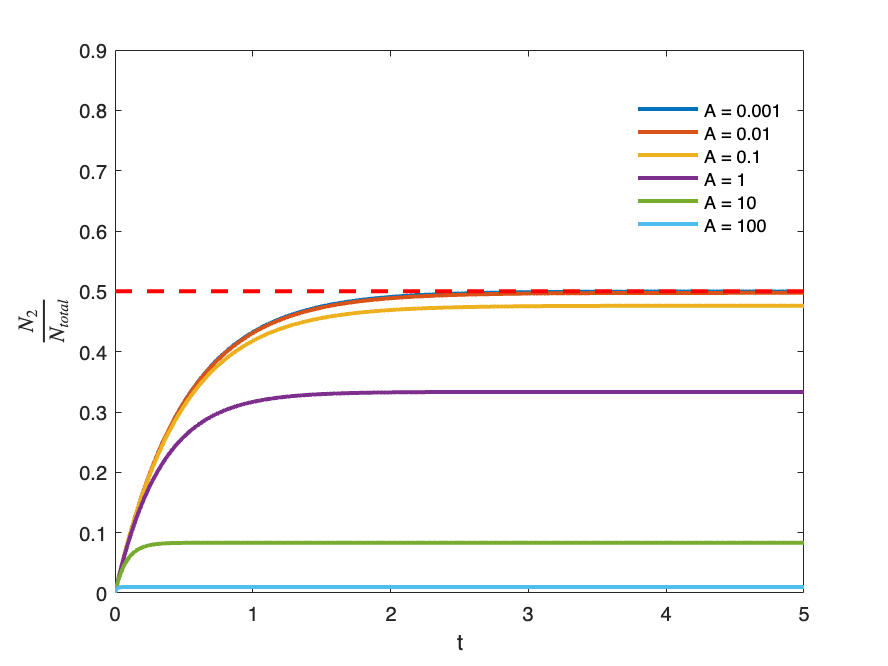

%simulate population dynamics for different spontaneous emission rates (A)

B_rho = 1; %stimulated transition rate

A_s = [0.001, 0.01, 0.1, 1, 10, 100]; %set of spontaneous emission rates

t = 0:0.01:5; %time points from 0 to 5 with step of 0.01

%plot setup
figure;
hold on;
box on;

%loop through each A and compute population
for A = A_s
    %solve for excited state fraction N2/Ntotal
    N2_Ntotal = B_rho./(2*B_rho+A).*(1-exp(-(2*B_rho+A).*t));
    
    %plot curve
    plot(t, N2_Ntotal, 'LineWidth', 2);
end

%reference line at 0.5
plot([0 5], [0.5 0.5], 'r--', 'LineWidth', 2);
%add legend with each A value labeled
legend(['A = ' num2str(A_s(1))], ['A = ' num2str(A_s(2))], ['A = ' num2str(A_s(3))], ['A = ' num2str(A_s(4))], ['A = ' num2str(A_s(5))], ['A = ' num2str(A_s(6))] ...
    ,'box','off', 'Position', [0.75, 0.7, 0.1, 0.1]);

%labeling
xlabel('t');
ylabel('$\frac{N_2}{N_{total}}$','Interpreter','latex');

%limiting y-axis for better visualization
ylim([0,0.9]);